This live script contains some basic test cases for the LampDesigner model

## Definitions

% Should be LED "C503B-ACN-CY0Z0252": 5.860cd - 12.000cd, 584nm - 596nm
amberLed = Led('Lumen III/C503B-ACN-CY0Z0252.xml')

amberLed =   LED "C503B-ACN-CY0Z0252": 5.860cd - 12.000cd, 584nm - 596nm

% Should be LED "C503B-RCN-CX0Y0AA1": 4.180cd - 8.200cd, 618nm - 630nm
redLed = Led('Lumen III/C503B-RCN-CX0Y0AA1.xml')

redLed =   LED "C503B-RCN-CX0Y0AA1": 4.180cd - 8.200cd, 618nm - 630nm

## Tests

Two arrays - one half the brightness of the other, 40deg apart. Note the red led has a dim spot in it's centre

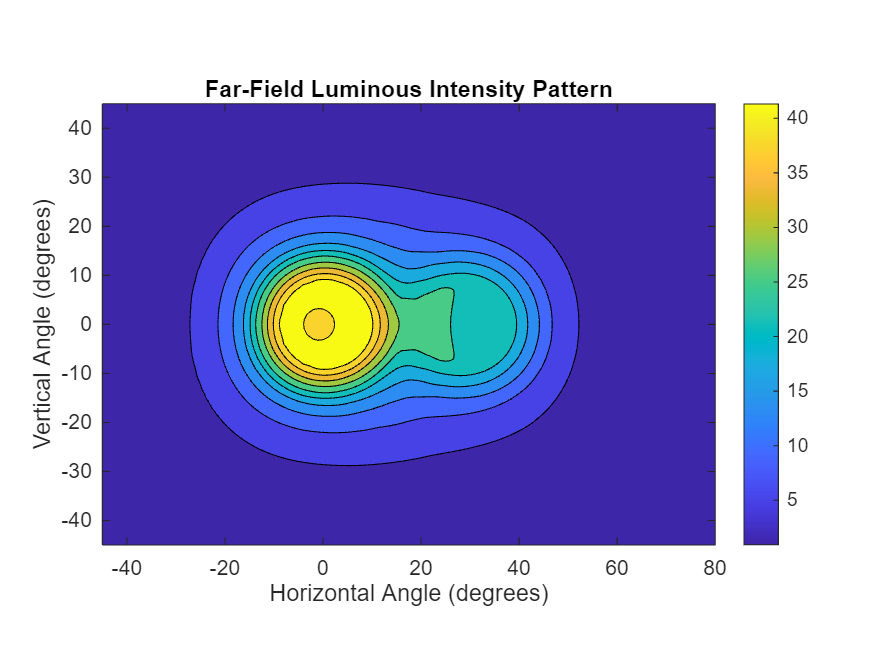

% Define the x and y field
[h, v] = meshgrid(-45:1:80, -45:1:45);

% Create the LedArray with 15 LEDs
ledArray = LedArray(redLed, 10, 0, 0);
ledArray2 = LedArray(redLed, 5, 30, 0);

% Initialize previous pattern with zeros
farFieldPattern = zeros(size(h));

% Compute far-field pattern (using min intensity mode = 0)
farFieldPattern = ledArray.GetFarFieldPattern(h, v, farFieldPattern, 0);
farFieldPattern = ledArray2.GetFarFieldPattern(h, v, farFieldPattern, 0);

% Plot the result as a contour plot
figure;
contourf(h, v, farFieldPattern, 10, 'LineColor', 'black');
axis equal;
colorbar;
xlabel('Horizontal Angle (degrees)');
ylabel('Vertical Angle (degrees)');
title('Far-Field Luminous Intensity Pattern');

As single cover, with 10deg vertical angle, placed over a uniform light of unity value

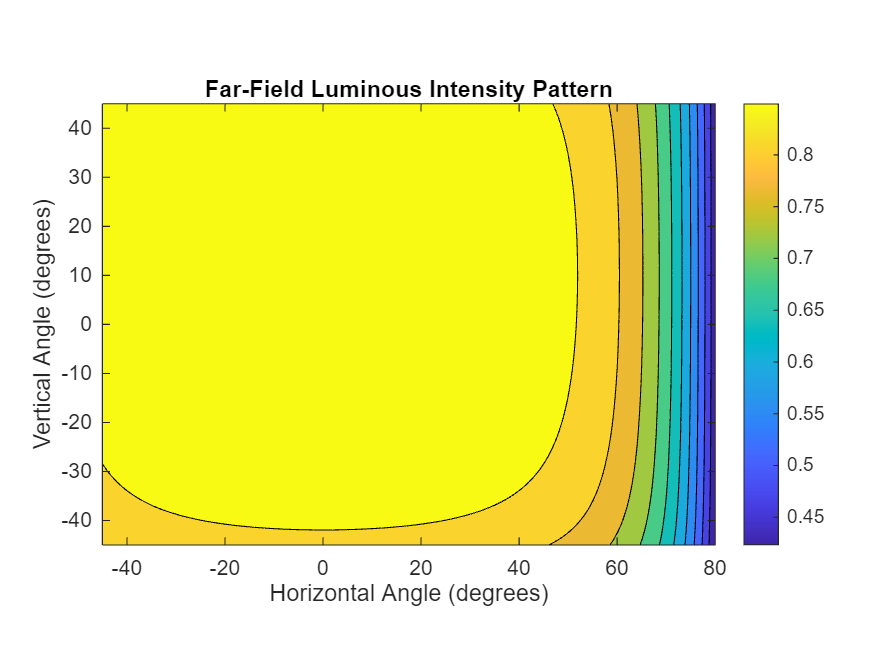

% Create a cover
polycarbonateFilm = FlatCover(1.3, 50.3212630904, 0.0008);

% Angle cover
cover1 = polycarbonateFilm.Angle(0,10);

% Compute far-field pattern (using min intensity mode = 0)
coverPattern = cover1.GetFarFieldPattern(h, v, ones(size(h)), 0);

% Plot the result as a contour plot
figure;
contourf(h, v, coverPattern, 10, 'LineColor', 'black');
axis equal;
colorbar;
xlabel('Horizontal Angle (degrees)');
ylabel('Vertical Angle (degrees)');
title('Far-Field Luminous Intensity Pattern');

Create a lamp with the two above led arrays, but with a trailing edge-style lamp cover

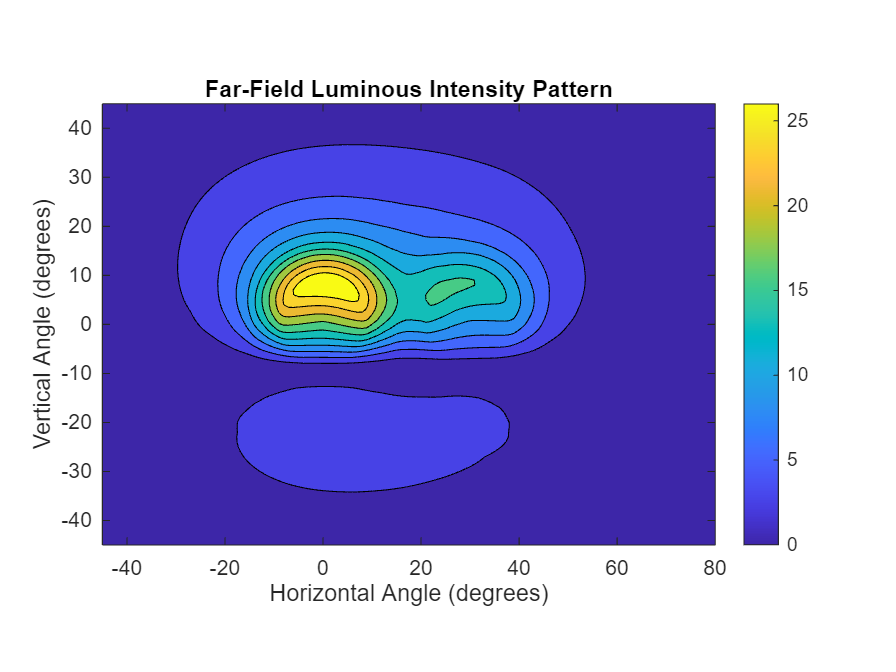

lamp = Lamp("Test");
lamp.Add(ledArray);
lamp.Add(ledArray2);
lamp.Add(polycarbonateFilm.Angle(0,80));

% Compute far-field pattern (using min intensity mode = 0)
coverPattern = lamp.GetFarFieldPattern(h, v, 0);

% Plot the result as a contour plot
figure;
contourf(h, v, coverPattern, 10, 'LineColor', 'black');
axis equal;
colorbar;
xlabel('Horizontal Angle (degrees)');
ylabel('Vertical Angle (degrees)');
title('Far-Field Luminous Intensity Pattern');

Validation of Test

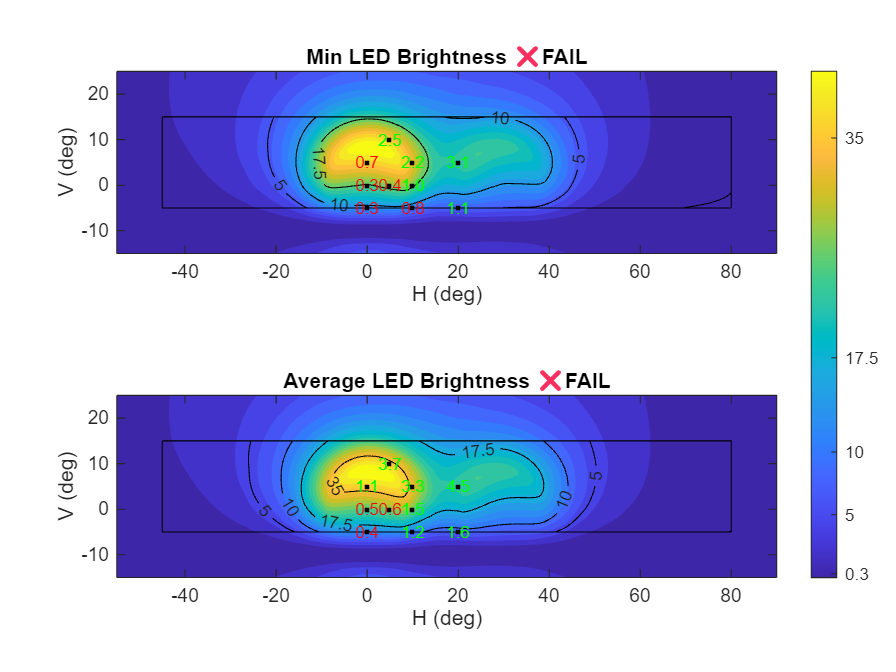

a3I = [0 0 100; 0 5 70; 0 -5 70; 5 0 90; 5 10 20; 5 -10 20; 10 0 35; 10 5 20; 10 -5 20; 20 5 10; 20 -5 10];
test = DistributionTest(0.3, 50, 500, -45, 80, 15, -5, a3I);
test.Validate(lamp);